Now reading C:\Users\alano\Desktop\images to be classified\Cropped smartphone photos\IMG_20200123_120453_BL.png


ans = 390

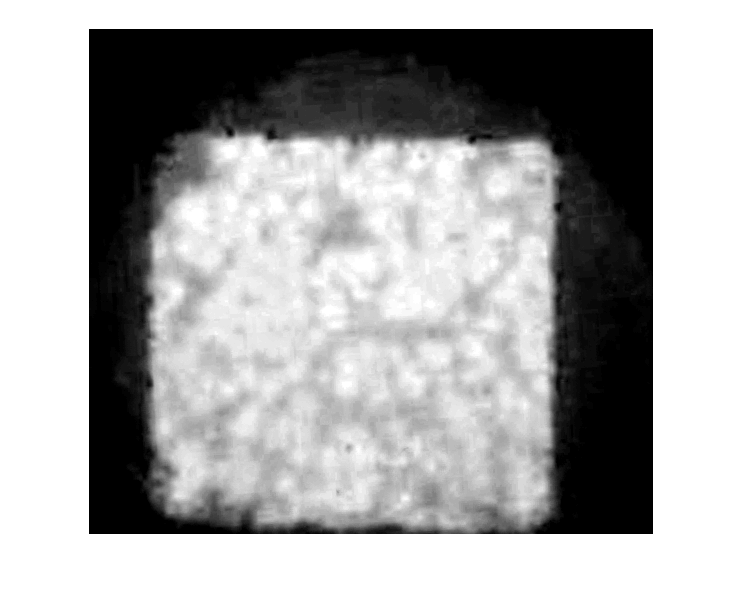

Now reading C:\Users\alano\Desktop\images to be classified\Cropped smartphone photos\IMG_20200123_120453_BR.png


ans = 362

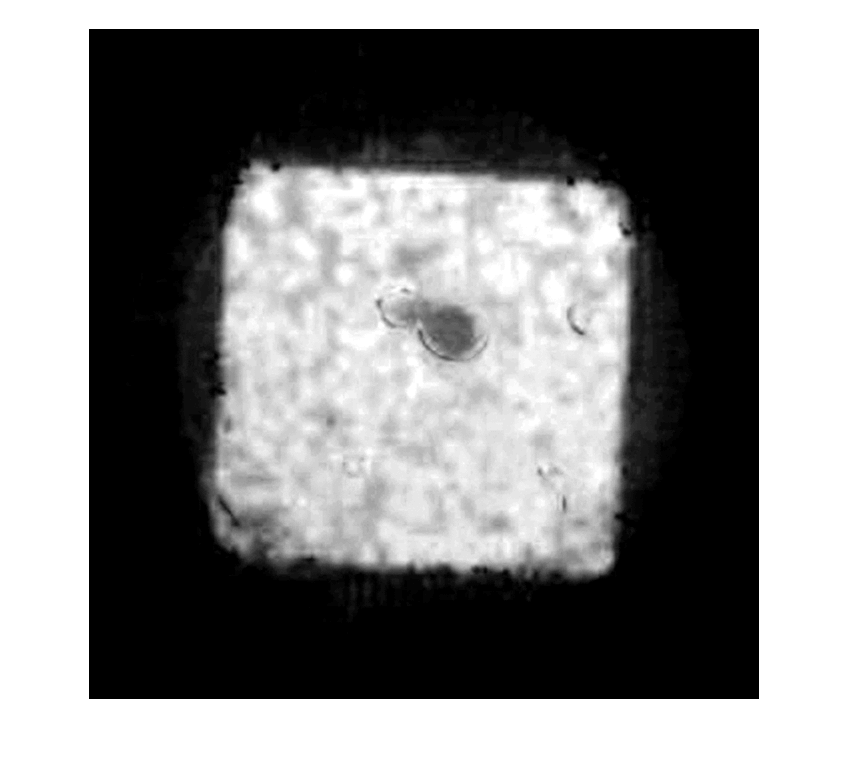

Now reading C:\Users\alano\Desktop\images to be classified\Cropped smartphone photos\IMG_20200123_120453_TL.png


ans = 326

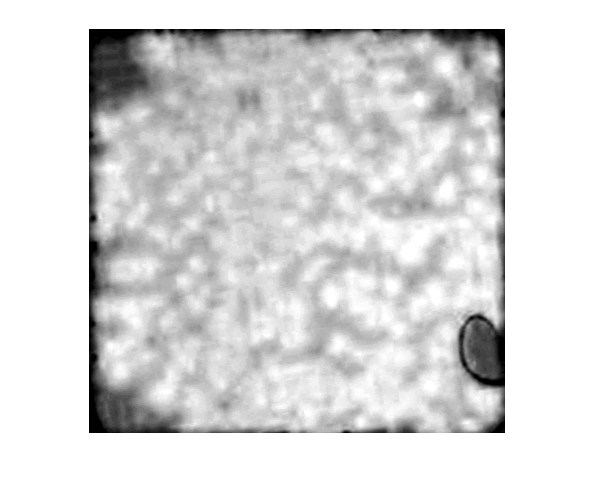

Now reading C:\Users\alano\Desktop\images to be classified\Cropped smartphone photos\IMG_20200123_120453_TR.png


ans = 323

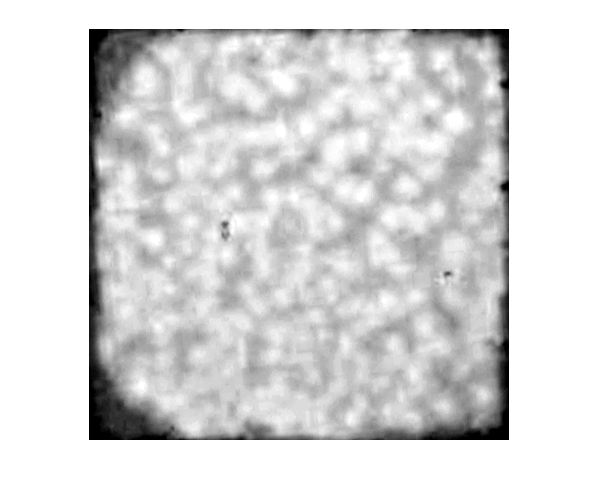

Now reading C:\Users\alano\Desktop\images to be classified\Cropped smartphone photos\IMG_20201117_185516_BL.png


ans = 344

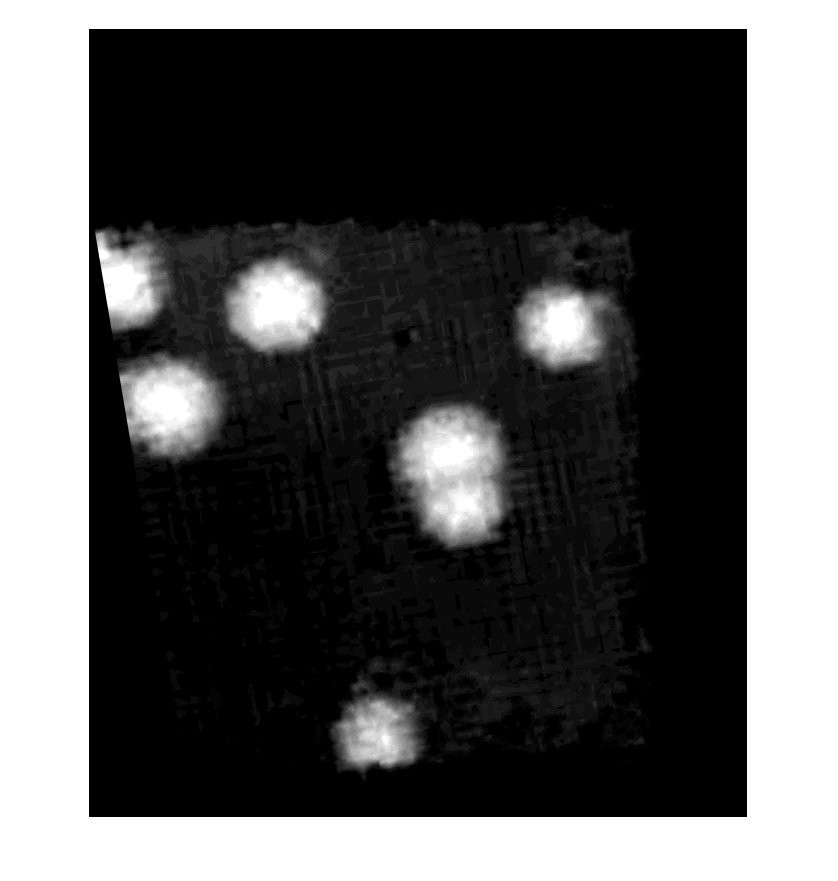

Now reading C:\Users\alano\Desktop\images to be classified\Cropped smartphone photos\IMG_20201117_185516_BR.png


ans = 378

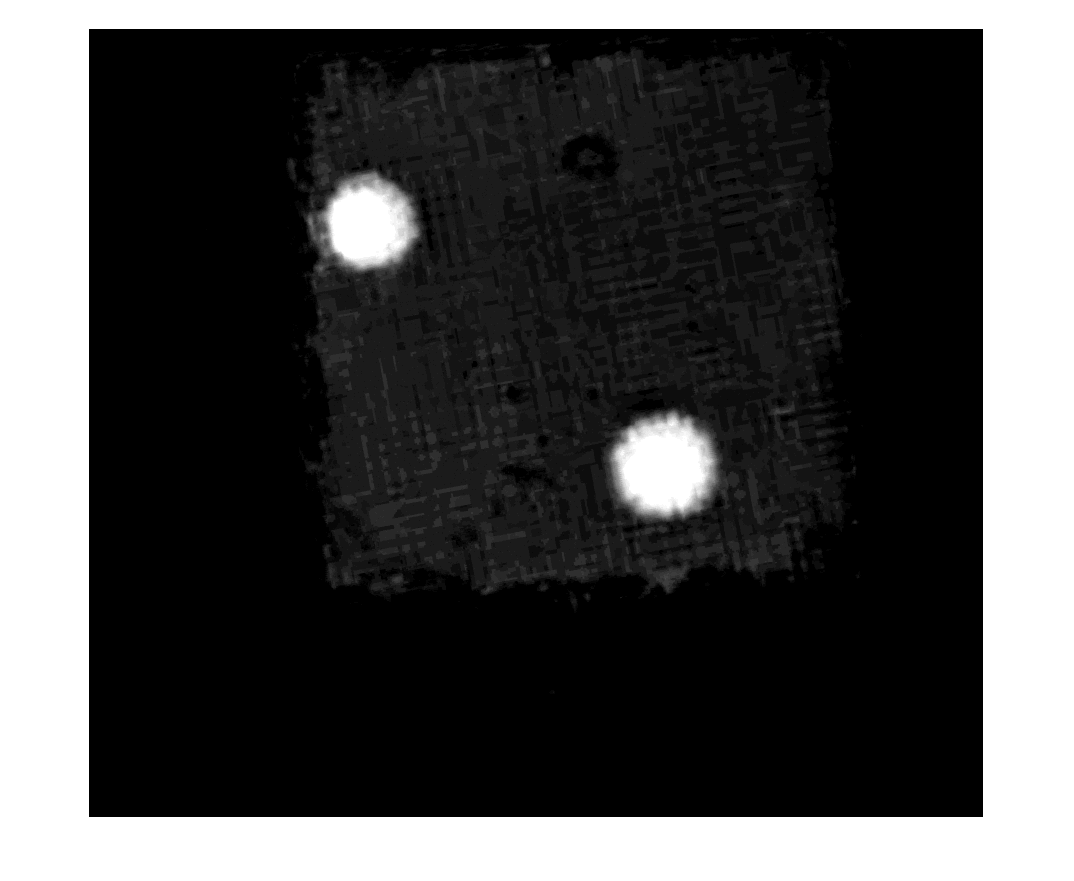

Now reading C:\Users\alano\Desktop\images to be classified\Cropped smartphone photos\IMG_20201117_185516_TL.png


ans = 497

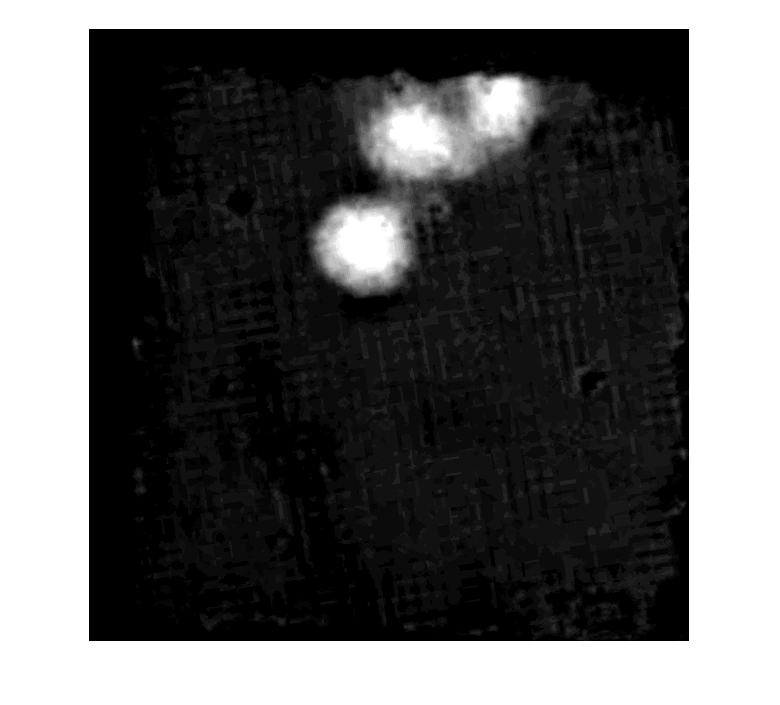

Now reading C:\Users\alano\Desktop\images to be classified\Cropped smartphone photos\IMG_20201117_185516_TR.png


ans = 393

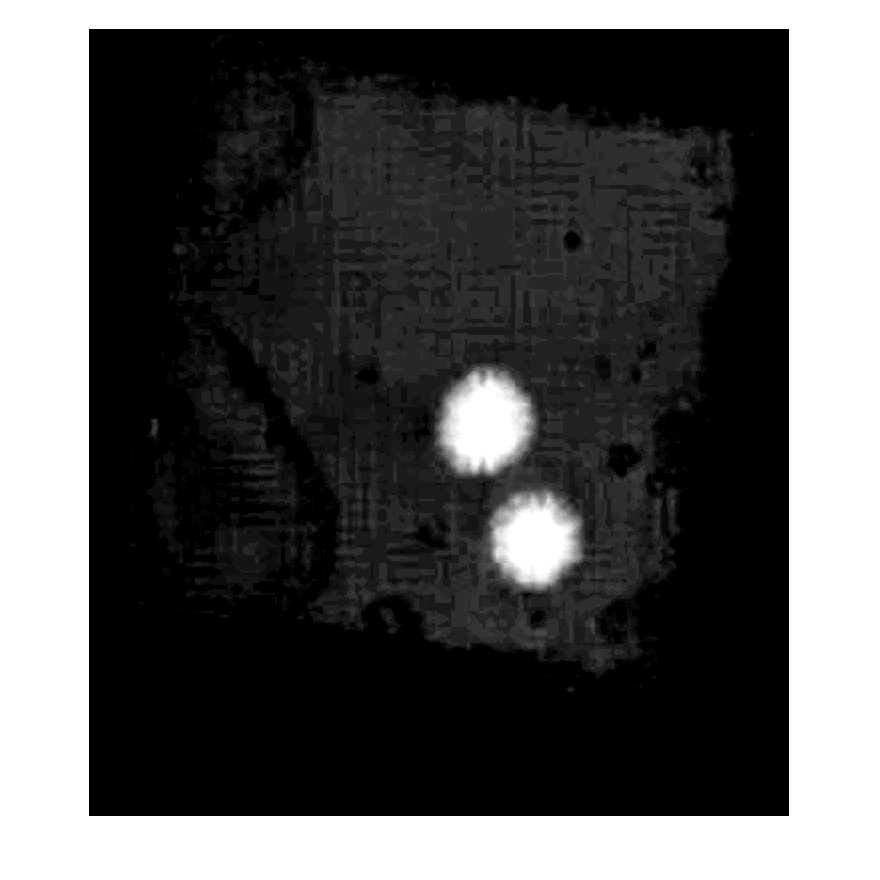

Now reading C:\Users\alano\Desktop\images to be classified\Cropped smartphone photos\IMG_20201204_165216~2_BL.png


ans = 493

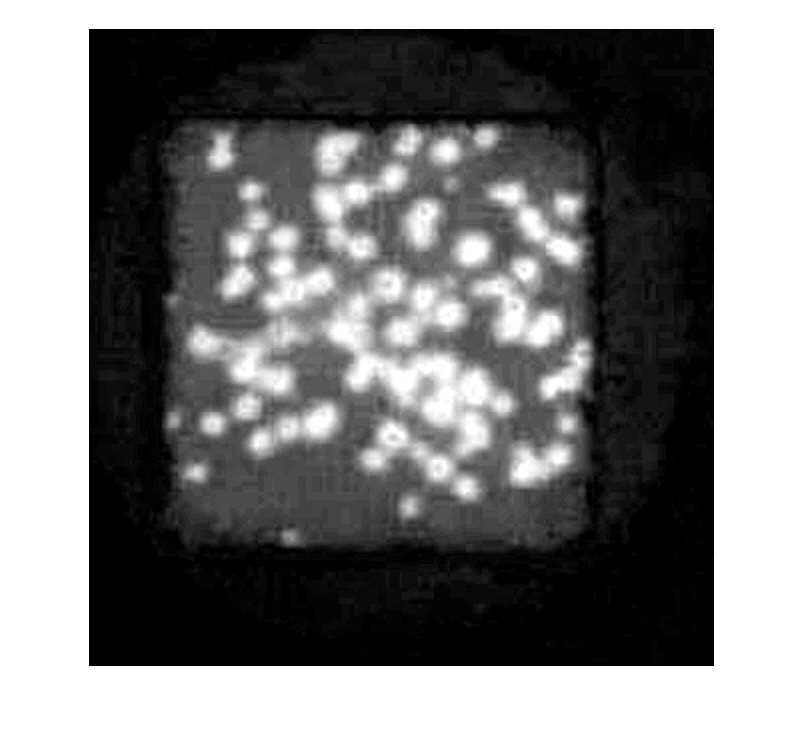

Now reading C:\Users\alano\Desktop\images to be classified\Cropped smartphone photos\IMG_20201204_165216~2_BR.png


ans = 618

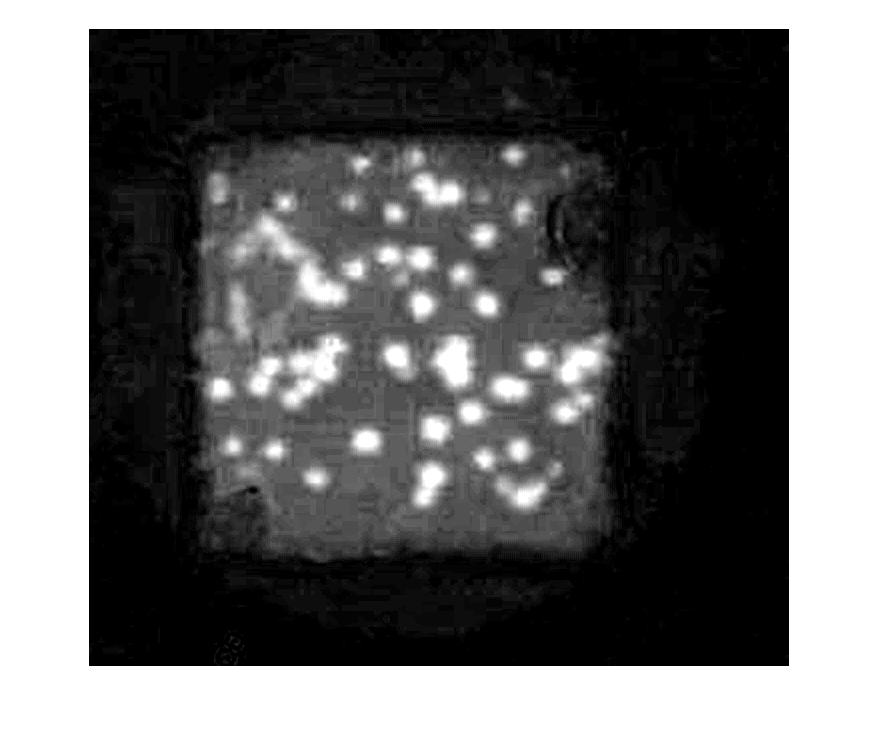

Now reading C:\Users\alano\Desktop\images to be classified\Cropped smartphone photos\IMG_20201204_165216~2_TL.png


ans = 469

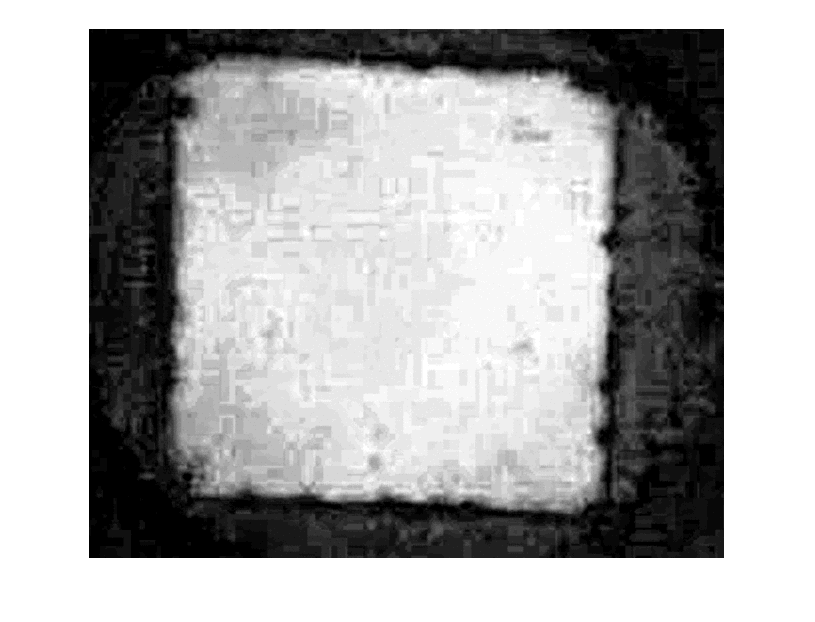

Now reading C:\Users\alano\Desktop\images to be classified\Cropped smartphone photos\IMG_20201204_165216~2_TR.png


ans = 490

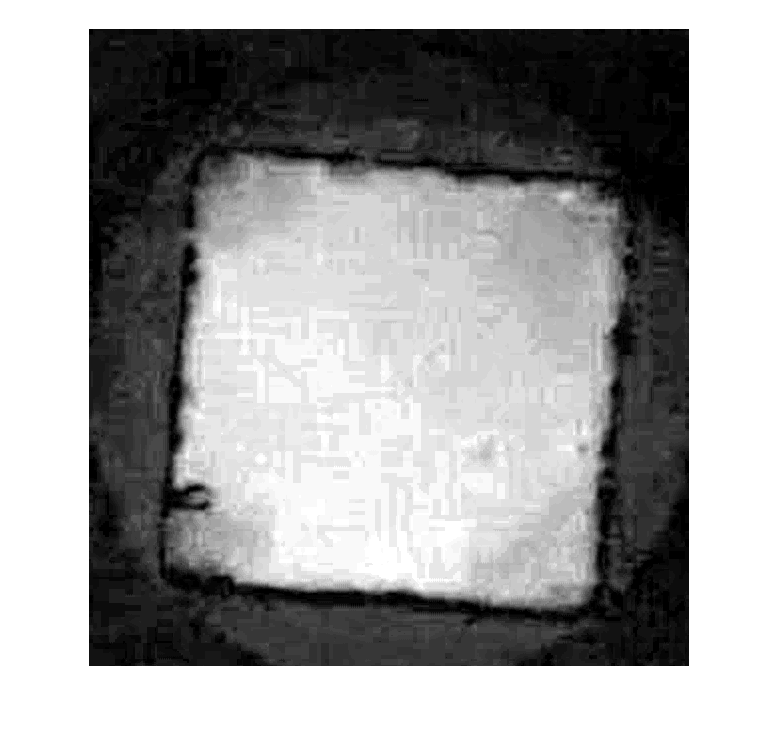

Now reading C:\Users\alano\Desktop\images to be classified\Cropped smartphone photos\IMG_20201218_132508~2_BL.png


ans = 170

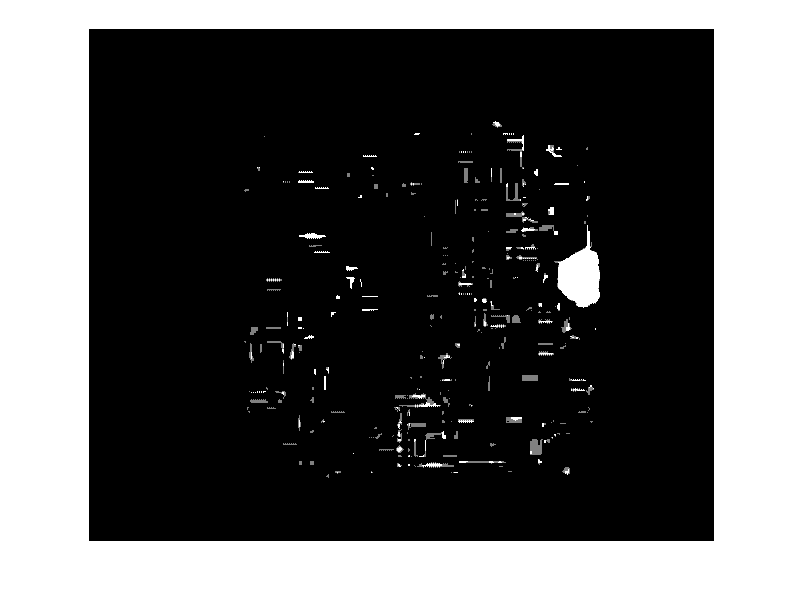

Now reading C:\Users\alano\Desktop\images to be classified\Cropped smartphone photos\IMG_20201218_132508~2_BR.png


ans = 217

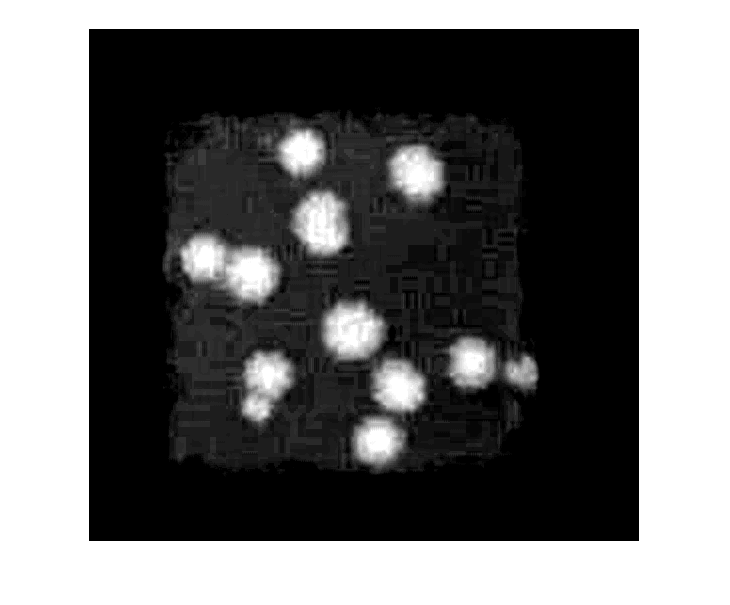

Now reading C:\Users\alano\Desktop\images to be classified\Cropped smartphone photos\IMG_20201218_132508~2_TL.png


ans = 36

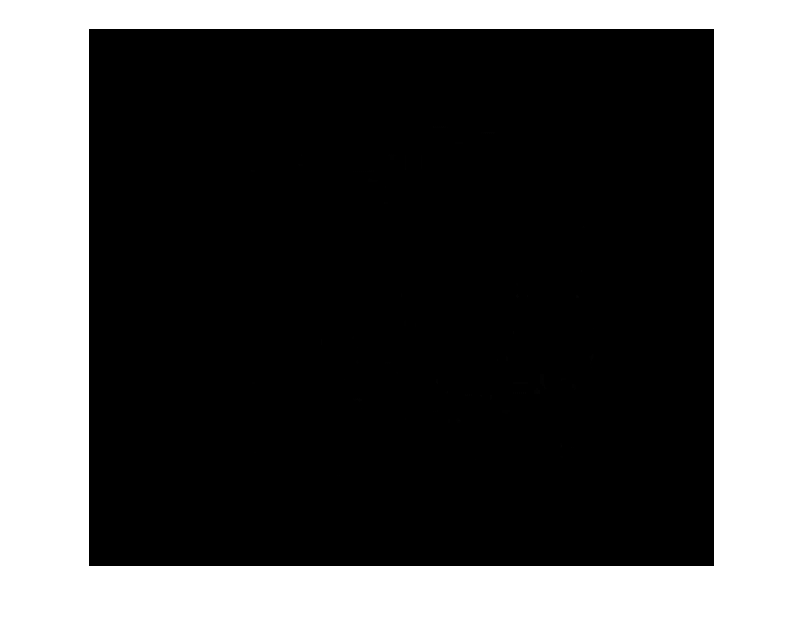

Now reading C:\Users\alano\Desktop\images to be classified\Cropped smartphone photos\IMG_20201218_132508~2_TR.png


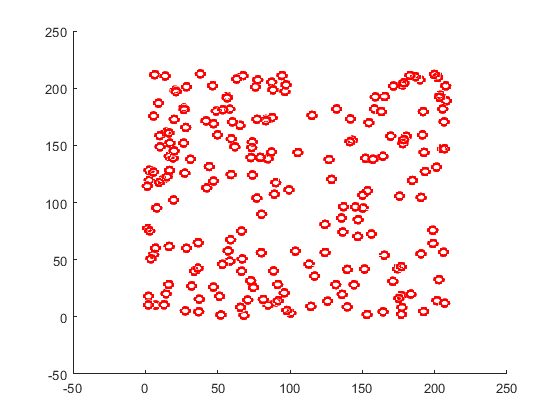

ans = 211

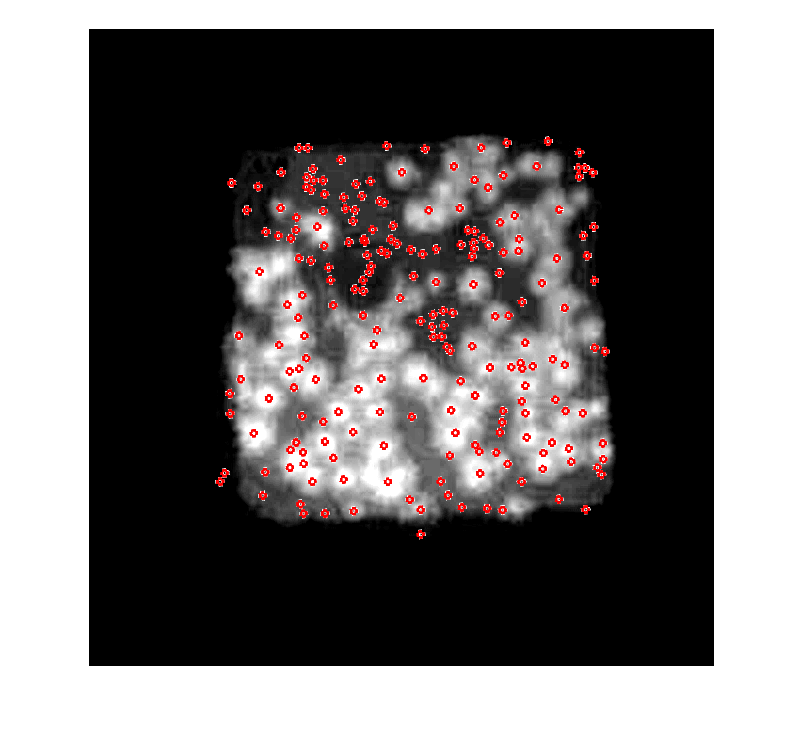

% Edited when migrating from microscope images to smartphone images:
% Lines 15

%change batchProcessing = true in SingleImageToImgEachDot.mlx

%param
myFolder = 'C:\Users\alano\Desktop\images to be classified\Cropped smartphone photos'; %change folder here

%main prog
if ~isfolder(myFolder)
  errorMessage = sprintf('Error: The following folder does not exist:\n%s', myFolder);
  uiwait(warndlg(errorMessage));
  return;
end
filePattern = fullfile(myFolder, '*.png'); %change img type here
jpegFiles = dir(filePattern);
for k = 1:length(jpegFiles)
  baseFileName = jpegFiles(k).name;
  fullFileName = fullfile(myFolder, baseFileName);
  fprintf(1, 'Now reading %s\n', fullFileName);
  SingleImageToImgEachDot;
end